# Task 1 - H-infinity loopshaping of generic 2nd order system

## Classic loopshaping

Design a robust controller for the following system:


$$G=\frac{1}{0\ldotp 0025s^2 +0\ldotp 06s+1}$$


(second order system with $\zeta =0\ldotp 6$ and $T=0\ldotp 05s$)

#### System definition

s = tf('s');
G = 1/(0.0025*s^2+0.06*s+1);

#### Sisotool loopshaping

Execute sisotool with the system G as the only parameter. 

%sisotool(G)

Add a pole at origin (integrator) and a zero at any location to the controller C. Move zero and adjust gain until you get satisfactory step response.

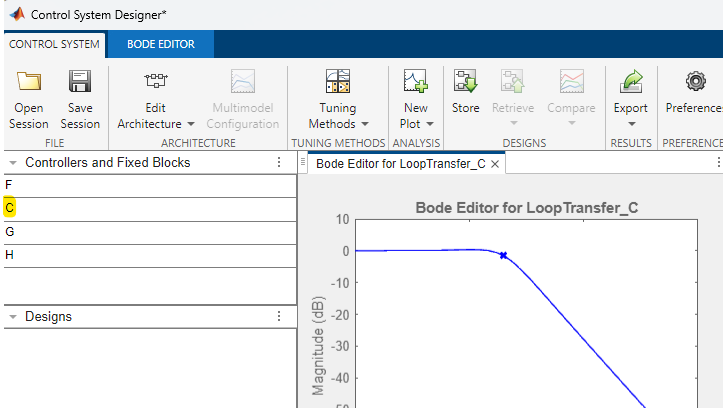

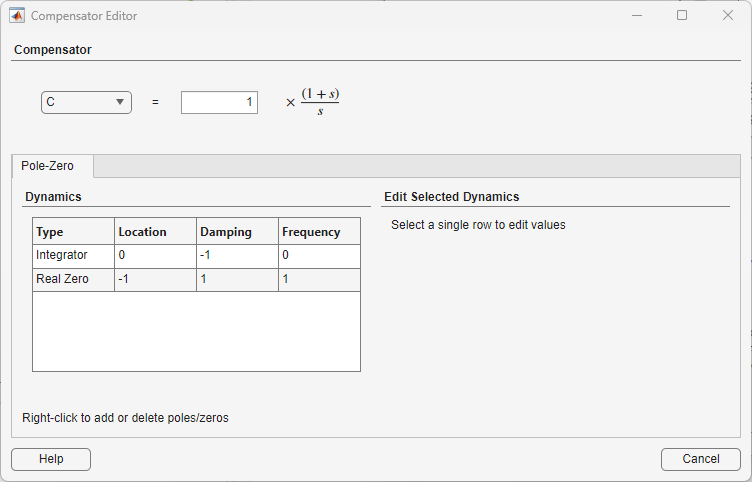

Store the controller values from sisotool into the variable W1, plot the open loop frequency response.

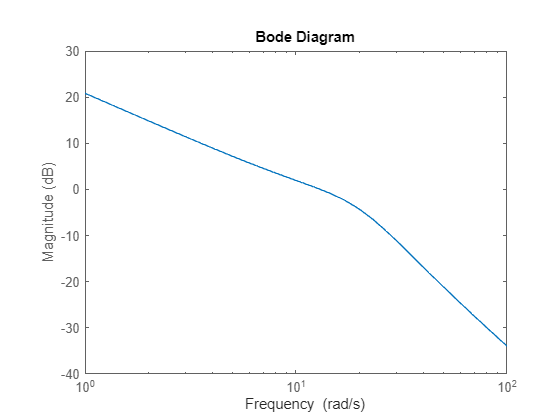

W1 = (0.484*s + 11)/s;
W2 = 1;

figure(1)
bodemag(W1*G);

Construct the closed loop with simple PI controller:

S0 = feedback(W1*G,-1,1);

## Robust controller calculation

Call function for robust controller synthesis using the plant and compensator as parameters (type help ncfsyn for more info).

[K,CL,GAM,INFO] = ncfsyn(G,W1);

Since $K=W_1 K_s W_2$ we need to "extract" the controller itself from INFO structure:

Ks = INFO.Ks;

Following control structure is required for controller implementation:

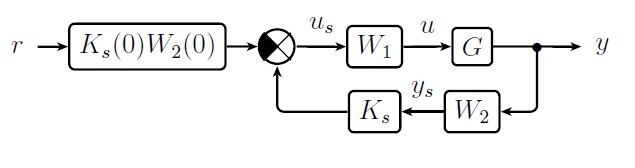

Where $K_s \left(0\right)$ and $W_2 \left(0\right)$ are gains of their respective transfer functions. You can calculate the gain using freqresp function at a frequency of 0 rad/sec. 

Ks0 = freqresp(Ks,0);
W20 = 1; % W2=1

#### Structure implementation in MATLAB

We need two transfer functions to analyze the closed loop behavior: the **sensitivity function S** ("control error transfer function") and **complementary sensitivity function T** ("setpoint transfer function"). We can plot even more functions to study specific closed loop properties - for example to see how large the control effort will be (the "KS" function). Notice the **negative** sign for the setpoint and more importantly the **positive** **feedback **in the schematic**:**

T = -Ks0*feedback(W1*G,INFO.Ks,1);
S = feedback(1,G*W1*INFO.Ks,1);

Plot the S, T, and S0 (regular PI closed loop) step response:

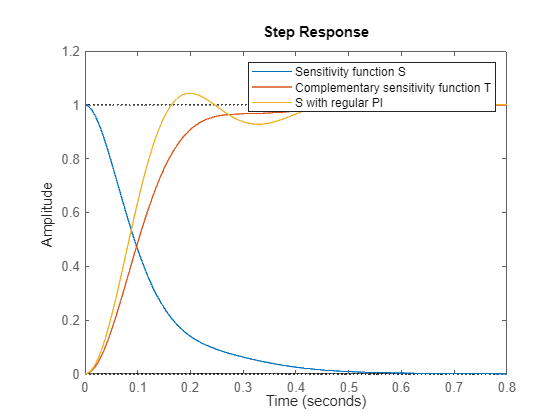

figure(2)
step(S,T,S0)
legend("Sensitivity function S","Complementary sensitivity function T","S with regular PI")

Plot the closed loop frequency responses:

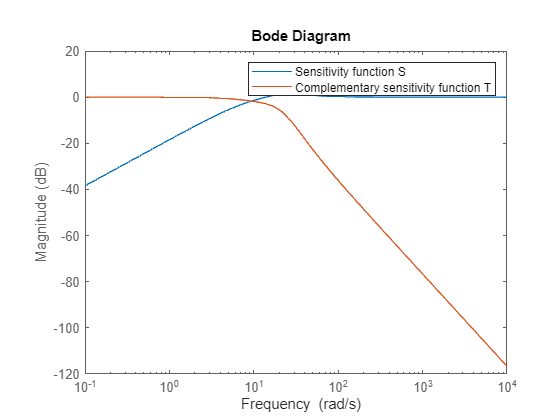

figure(3)
bodemag(S,T)
legend("Sensitivity function S","Complementary sensitivity function T")

# Task 2 - $H_{\infty }$ loopshaping of mass-spring-damper state-space system with uncertainties

Model of the MSD is taken from the exercise 7 - uncertainties. See the previous exercise for details about this system.

## Uncertain state-space model of MSD

First we need to define uncertain parameters of the system. In the case of MSD it's mass, stiffness and damping. Each of these parameters can deviate from the nominal value by a percentage deviation. Function ureal can take these nominal values and deviations to create an object that can be later used to define a system as any other constant parameter.

mnom = 3;
cnom = 1;
knom = 2;
pm = 40; % max deviation from nominal value 40%
pc = 40; %
pk = 30; %

m = ureal('mass',mnom,'Percentage',pm);
c = ureal('friction',cnom,'Percentage',pc);
k = ureal('elasticity',knom,'Percentage',pk);

System definition starts with the system matrices. Any system (state-space or transfer function) that uses the uncertain parameter will itself become uncertain system. 

% system matrices with uncertain parameters
A = [  0     1
    -k/m  -c/m];
B = [0;
    1/m];
C = [1 0];

D = [0];


Use the uss function to form uncertain state space description, regular ss works as well.

Gunct = uss(A,B,C,D);

Plot the frequency response of the uncertain system

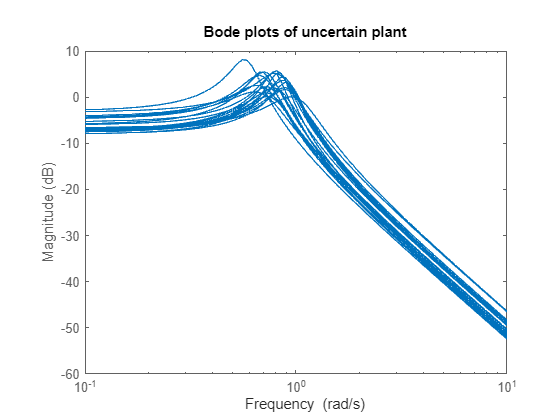

omega = logspace(-1,1,100);
figure(4)
bodemag(Gunct,omega)
title('Bode plots of uncertain plant')

## Loopshaping design procedure

Open sisotool with the system G. Sisotool will automatically  select the nominal plant (it doesn't directly support uss).

%sisotool(G)

Design the PI controller and transfer the resulting parameters into the W1 variable. 

s = tf('s');
W1 = (80*s+20)/s;

Form open loop and check the frequency response:

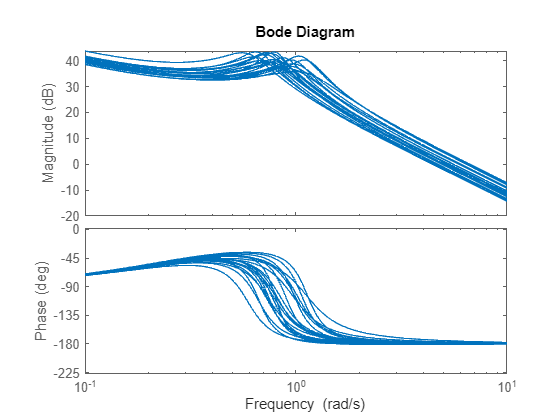

L = W1*Gunct;
figure(5)
bode(L,omega)

Controller synthesis using uncertain plant Gss and compensator W1 (type help ncfsyn for more info).

[K,CL,GAM,INFO] = ncfsyn(Gunct,W1);


## Controller implementation 

Get the controller and its gain for zero frequency:

Ks = INFO.Ks;
Ks0 = freqresp(Ks,0);

Implement the control feedback loop using uncertain model and robust controller:

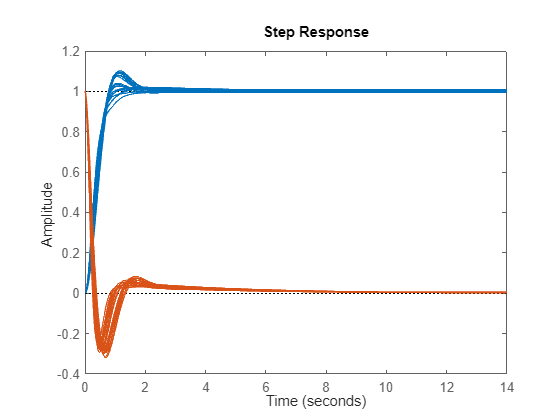

Tunct = -Ks0*feedback(W1*Gunct,Ks,+1);
Sunct = feedback(1,W1*Gunct*Ks,+1);
figure(6)
step(Tunct, Sunct)

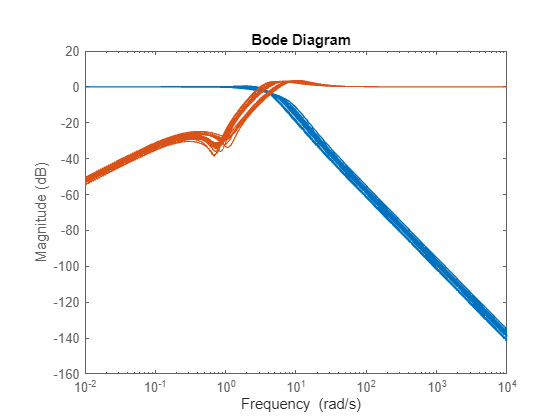

figure(7)
bodemag(Tunct, Sunct)